# TIME

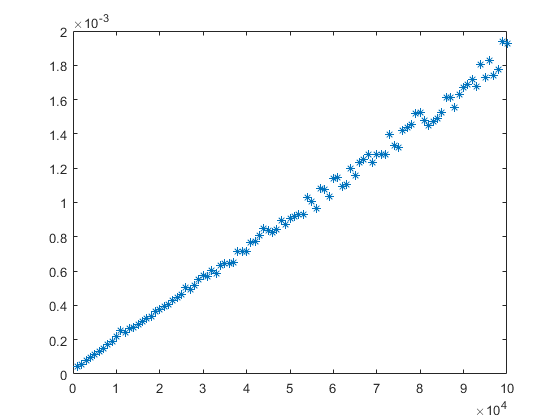

rng('shuffle')
format long

sequences = 1000:1000:100000;
T = [zeros(1,length(sequences))];
B_a = [ones(length(sequences),2)];
for t = 1:length(sequences)
    g = @() rand_vector(sequences(t));
    T(t) = timeit(g);
    B_a(t,2) = [sequences(t)];
end
plot(sequences,T,"*")

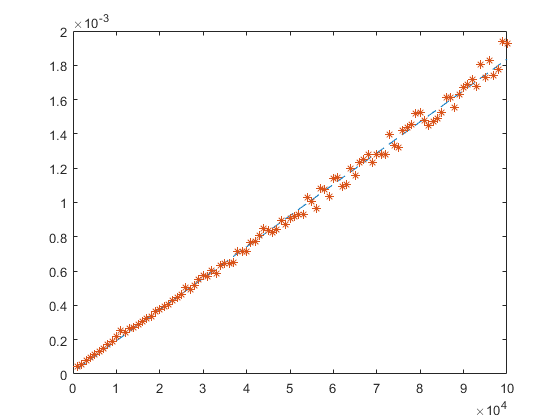

X = sequences';
Y = T';


A = B_a;
c=A\Y;
%c=(A'*A)\A'*Y
YY=c(1)+c(2)*X;
plot(X,YY,'--',X,Y,'*')

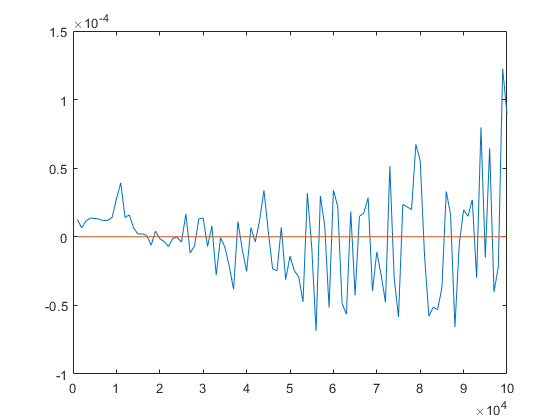

plot(X,Y-YY,X,X*0)

RSS=sum((Y-YY).^2)

RSS =      1.111995358923630e-07


A = [ones(length(Y),1),X,X.^2]

A = 	1.0e+10 *

   0.000000000100000   0.000000100000000   0.000100000000000
   0.000000000100000   0.000000200000000   0.000400000000000
   0.000000000100000   0.000000300000000   0.000900000000000
   0.000000000100000   0.000000400000000   0.001600000000000
   0.000000000100000   0.000000500000000   0.002500000000000
   0.000000000100000   0.000000600000000   0.003600000000000
   0.000000000100000   0.000000700000000   0.004900000000000
   0.000000000100000   0.000000800000000   0.006400000000000
   0.000000000100000   0.000000900000000   0.008100000000000
   0.000000000100000   0.000001000000000   0.010000000000000


c=(A'*A)\A'*Y

c = 	1.0e+-4 *

   0.372850627197359
   0.000167206420155
   0.000000000150942


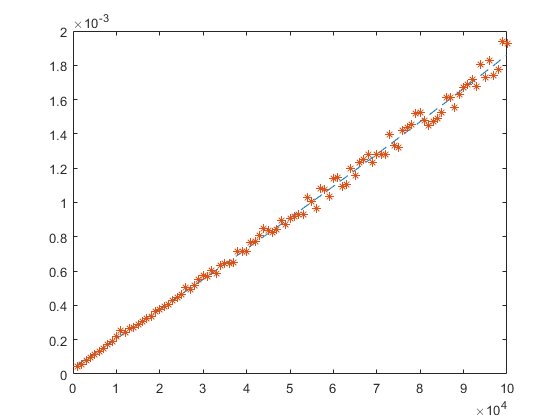

YY=c(1)+c(2)*X+c(3)*X.^2;
plot(X,YY,'--',X,Y,'*')

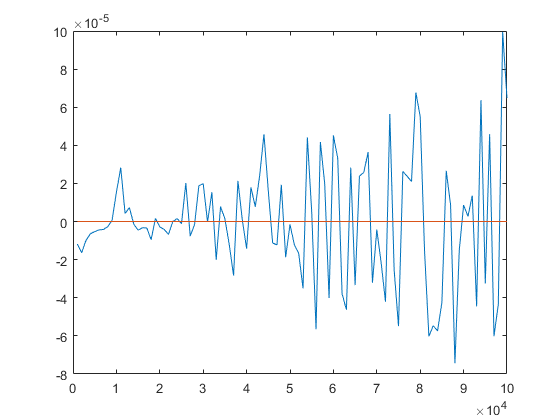

plot(X,Y-YY,X,X*0)

RSS=sum((Y-YY).^2)

RSS =      9.854829542875547e-08


A = [[ones(length(Y),1),X,X.*log(X)]]

A = 	1.0e+06 *

   0.000001000000000   0.001000000000000   0.006907755278982
   0.000001000000000   0.002000000000000   0.015201804919084
   0.000001000000000   0.003000000000000   0.024019102702951
   0.000001000000000   0.004000000000000   0.033176198560408
   0.000001000000000   0.005000000000000   0.042585965957081
   0.000001000000000   0.006000000000000   0.052197088489261
   0.000001000000000   0.007000000000000   0.061975657996262
   0.000001000000000   0.008000000000000   0.071897574565296
   0.000001000000000   0.009000000000000   0.081944818706865
   0.000001000000000   0.010000000000000   0.092103403719762


c=(A'*A)\A'*Y

c = 	1.0e+-4 *

   0.475234508244339
   0.000058657902805
   0.000010585790997


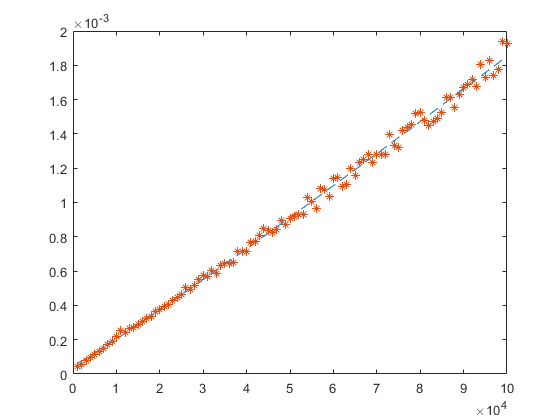

YY=c(1)+c(2)*X+c(3)*X.*log(X);
plot(X,YY,'--',X,Y,'*')

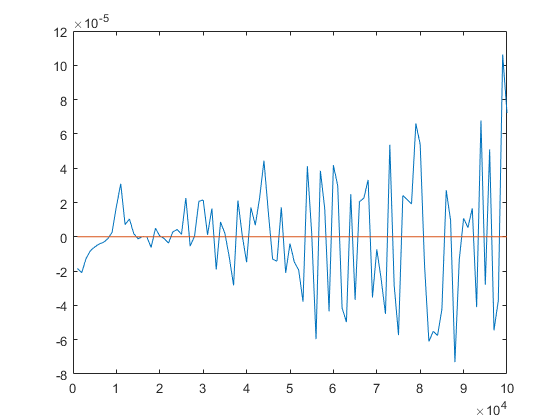

plot(X,Y-YY,X,X*0)

RSS=sum((Y-YY).^2)

RSS =      1.012672963317951e-07


A = [ones(length(Y),1),X,X.^2,X.*log(X)]

A = 	1.0e+10 *

   0.000000000100000   0.000000100000000   0.000100000000000   0.000000690775528
   0.000000000100000   0.000000200000000   0.000400000000000   0.000001520180492
   0.000000000100000   0.000000300000000   0.000900000000000   0.000002401910270
   0.000000000100000   0.000000400000000   0.001600000000000   0.000003317619856
   0.000000000100000   0.000000500000000   0.002500000000000   0.000004258596596
   0.000000000100000   0.000000600000000   0.003600000000000   0.000005219708849
   0.000000000100000   0.000000700000000   0.004900000000000   0.000006197565800
   0.000000000100000   0.000000800000000   0.006400000000000   0.000007189757457
   0.000000000100000   0.000000900000000   0.008100000000000   0.000008194481871
   0.000000000100000   0.000001000000000   0.010000000000000   0.000009210340372


c=(A'*A)\A'*Y

c = 	1.0e+-4 *

   0.146182441322625
   0.000348081323046
   0.000000000363032
  -0.000017298638374


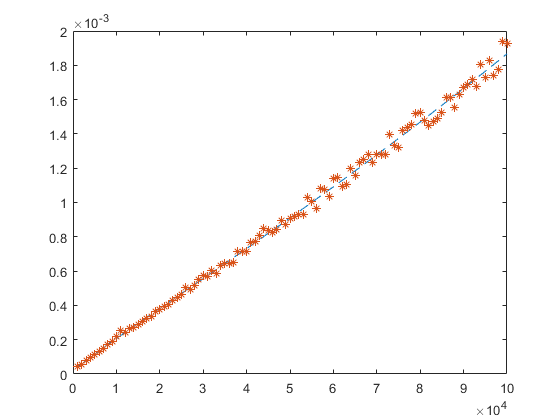

YY=c(1)+c(2)*X+c(3)*X.^2+c(4)*X.*log(X);
plot(X,YY,'--',X,Y,'*')

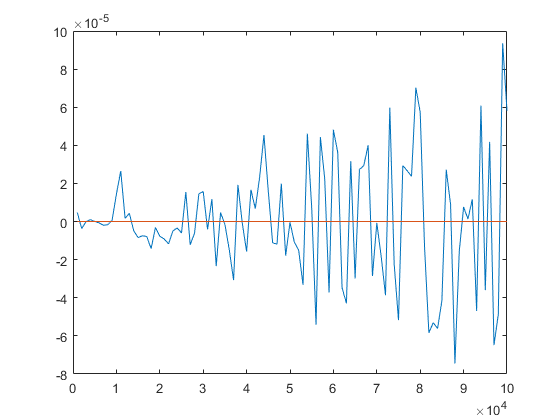

plot(X,Y-YY,X,X*0)

RSS=sum((Y-YY).^2)

RSS =      9.700266340310590e-08


function [vec] = rand_vector(n)
    vec = rand(1,n);
    vec = sort(vec);
end